# PCG Signal

Copyright (C) 2022 Miodrag Bolic

 This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIOVASCULAR AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

We would like to acknowledge **Introduction: Examination for Heart Sounds & Murmurs  **at  [https://depts.washington.edu/physdx/heart/index.html](https://depts.washington.edu/physdx/heart/index.html) as well as P. Bentley, G. Nordehn, M. Coimbra, and S. Mannor, “T**he PASCAL Classifying Heart Sounds Challenge 2011** (CHSC2011) Results.” http://www.peterjbentley.com/heartchallenge/index.html, 2011. Waveforms that are used here are downloaded from their websites.                             

## Introduction

In this notebook we show several PCG signals. 

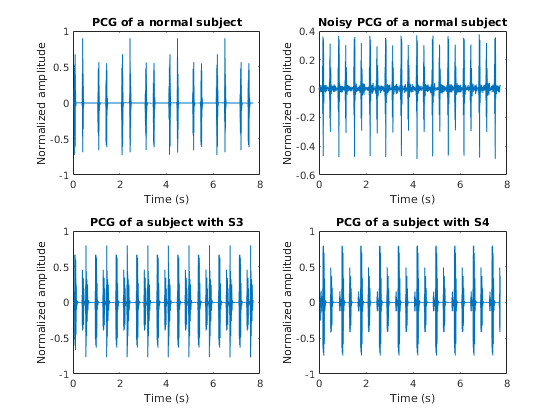


signal_normal = audioread('normal.mp3');
signal_noisy_normal = audioread('201108011118.wav');
signal_s3 = audioread('s31.mp3');
signal_s4 = audioread('s41.mp3');
fs=44100;
Ts = 1/fs;
S_num=340000;
t=1/fs:1/fs:S_num/fs;
figure,
subplot(221)
plot(t,signal_normal(1:S_num))  
title('PCG of a normal subject')
xlabel('Time (s)')
ylabel('Normalized amplitude')

subplot(222)
plot(t,signal_noisy_normal(1:S_num))  
title('Noisy PCG of a normal subject')
xlabel('Time (s)')
ylabel('Normalized amplitude')

subplot(223)
plot(t,signal_s3(1:S_num))  
title('PCG of a subject with S3')
xlabel('Time (s)')
ylabel('Normalized amplitude')

subplot(224)
plot(t,signal_s4(1:S_num))  
title('PCG of a subject with S4')
xlabel('Time (s)')
ylabel('Normalized amplitude')

exportgraphics(gcf,"Fig10.5", 'Resolution',600)

Error using exportgraphics
File format '4' is not valid for export.


figure
stft(signal_noisy_normal,fs,'Window',kaiser(256,5),'OverlapLength',220,'FFTLength',2^12);
view(-45,65)
colormap jet
zlim([-50,100])
ylim([-5,5])


%signal1=signal_noisy_normal;
%S1detect_MFCC_final_VM